%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 151433*0.946

W = 1.4326e+05


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1561; %ft^2
AR = 8.75

AR = 8.7500

AR2 = 5.23

AR2 = 5.2300

b2=100

b2 = 100

TaperRatio = 0.6;
b = sqrt(AR*S)

b = 116.8707

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.9;
K = 1/(e*pi*AR)

K = 0.0404


%Fuselage Parameters
Df = 15.17; %ft
LNose = 13.33; %ft
LMid = 44; %ft
LTail = 37.3 %ft

LTail = 37.3000

DBase = 1.5 %ft

DBase = 1.5000

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 590.8000

M = 0.5817

Cr = 16.6958

Cmac = 13.6349

Ymac = 26.7829

SweepMaxT = -0.9821

Cf = 15.8290

Sexp = 1.3143e+03

Re = 4.4977e+07

SweepMaxT = -0.9821

FF = 1.5505

Swet = 2.7009e+03

CDo = 0.0062


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 590.8000

M = 0.5817

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 2.8050e+07

SweepMaxT = -1.7183

FF = 1.4906

Swet = 815.7600

CDo = 0.0079


CDoHt = CDoHt*Sh/S

CDoHt = 0.0020


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 590.8000

M = 0.5817

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 3.1286e+07

SweepMaxT = -0.9437

FF = 1.4907

Swet = 1.2236e+03

CDo = 0.0077


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0015


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.2628

CDoFuse = 0.0060


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0062


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0036


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag

CDoTotal = 0.0219


%Induced Drag Factor
% [TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
% AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
% V=V*1.688
% M = V/SpeedSound
% 
% Ne = 0; %Num of engines ON TOP of Wing
% TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
% K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)


CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
   CD2(x) = CDoTotal2 + K2*CL(x)^2
   
   if CL(x)/CD2(x)>LDMax
       
       LDMax2 = CL(x)/CD2(x)
       
   end
   
end

CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 =     0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245    0.0243    0.0240    0.0237    0.0235    0.0233    0.0231    0.0229    0.0227    0.0225    0.0224    0.0222    0.0221    0.0220    0.0219    0.0218    0.0217    0.0217    0.0216    0.0216    0.0216


CD =     0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237    0.0235    0.0233    0.0232    0.0230    0.0229    0.0228    0.0227    0.0226    0.0225    0.0224    0.0223    0.0222    0.0221    0.0221    0.0220    0.0220    0.0219    0.0219    0.0219    0.0219


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 0.4570

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 0.4640

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 0.9134

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 0.9271

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 1.3689

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 1.3885

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 1.8229

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 1.8473

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 2.2748

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 2.3026

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 2.7243

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 2.7537

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 3.1707

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 3.1997

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 3.6138

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 3.6400

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 4.0529

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 4.0737

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 4.4877

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 4.5001

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 4.9178

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


LDMax2 = 4.9187

CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 5.3426

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 5.7619

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 6.1753

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 6.5823

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 6.9827

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 7.3762

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 7.7625

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 8.1412

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 8.5122

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 8.8752

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 9.2300

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 9.5765

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 9.9145

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 10.2438

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 10.5643

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 10.8759

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 11.1786

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 11.4723

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 11.7570

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 12.0326

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 12.2992

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 12.5568

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 12.8053

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 13.0449

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 13.2756

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 13.4975

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 13.7107

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 13.9153

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 14.1113

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 14.2989

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 14.4783

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 14.6495

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 14.8127

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 14.9681

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 15.1158

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 15.2559

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 15.3887

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 15.5143

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 15.6329

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 15.7445

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 15.8496

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 15.9480

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.0402

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.1262

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.2062

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.2804

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.3490

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.4121

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.4699

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.5225

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.5703

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.6132

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.6515

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.6853

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.7148

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.7402

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.7615

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.7789

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.7927

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.8029

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.8096

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.8130

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


LDMax = 16.8132

CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


CD = 1×30
    0.0320    0.0316    0.0312    0.0308    0.0304    0.0301    0.0297    0.0294    0.0290    0.0287    0.0283    0.0280    0.0277    0.0274    0.0271    0.0268    0.0266    0.0263    0.0260    0.0258    0.0255    0.0253    0.0250    0.0248    0.0246    0.0244    0.0242    0.0240    0.0238    0.0237


CD2 = 1×30
    0.0385    0.0378    0.0371    0.0365    0.0359    0.0352    0.0346    0.0340    0.0335    0.0329    0.0324    0.0318    0.0313    0.0308    0.0303    0.0298    0.0294    0.0289    0.0285    0.0280    0.0276    0.0272    0.0268    0.0265    0.0261    0.0258    0.0254    0.0251    0.0248    0.0245


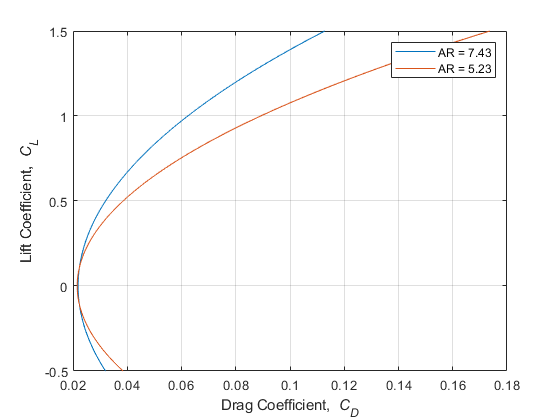


plot (CD,CL)
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
hold on
plot (CD2,CL)
hold off
legend('AR = 7.43','AR = 5.23')


LDMax

LDMax = 16.8132

LDMax2

LDMax2 = 4.9187